# Project 2 - OCT Angiography

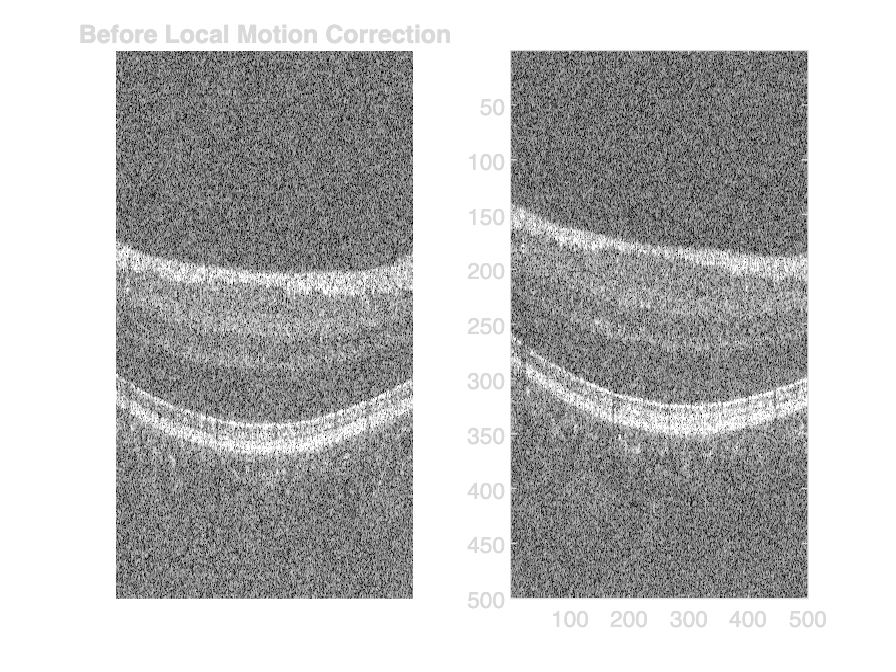

clear all; clc; close all;
load(fullfile('OCT_BM_DBD.mat'));

for i = 1:size(OCT_BM_DBD)
   imagesc(imadjust(mat2gray(squeeze(20.*log10(abs(OCT_BM_DBD(:,:,i))))))); colormap("gray"); pause(0.01);
end

## Local Motion Correction

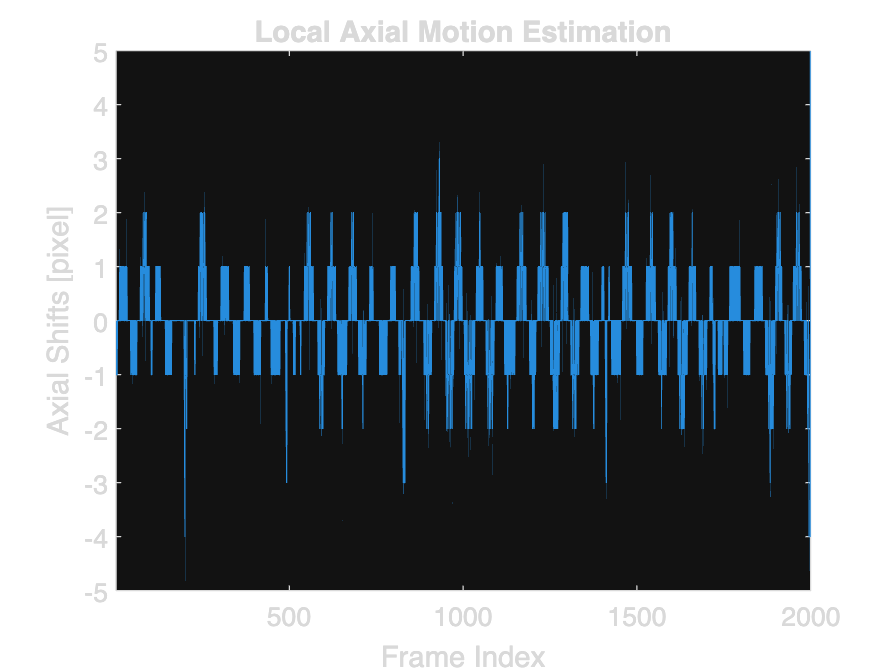

usfac = 1;
numAscans = size(OCT_BM_DBD,2);
numBscans = size(OCT_BM_DBD,3);
numCscans = numBscans/numAscans;

local_axial_motion = zeros([numBscans 1]);
local_lateral_motion = zeros([numBscans 1]);

OCT_BM_DBD_mcorr = OCT_BM_DBD;

for I = 1:numCscans:numBscans
    for J = 1:numCscans-1
        [output, ~] = dftregistration(fft2(20.*log10(abs(OCT_BM_DBD(:,:,I)))), fft2(20.*log10(abs(OCT_BM_DBD(:,:,I+J)))), usfac);
        local_axial_motion(I+J) = round(output(3));
        local_lateral_motion(I+J) = round(output(4));
        OCT_BM_DBD_mcorr(:,:,I+J) = circshift(OCT_BM_DBD(:,:,I+J), [round(output(3)) round(output(4))]);
    end
end

plot(local_axial_motion);
xlim([1 2000]); ylim([-5 5]);
title('Local Axial Motion Estimation');
xlabel('Frame Index');
ylabel('Axial Shifts [pixel]');

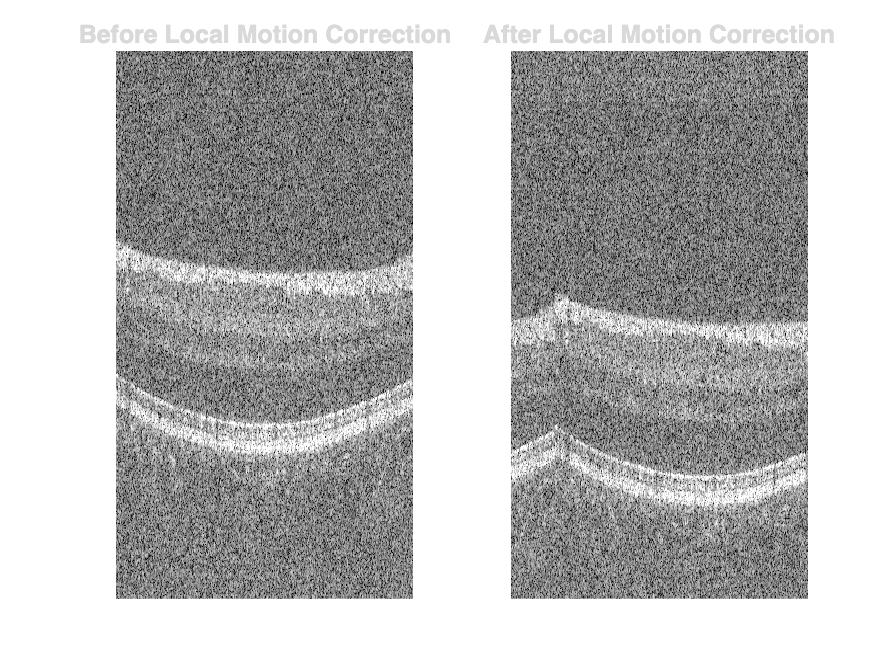


for i = 1:size(OCT_BM_DBD_mcorr,3)
    subplot(1,2,1)
    imagesc(imadjust(mat2gray(20.*log10(abs(squeeze(OCT_BM_DBD(:,:,i)))))));
    colormap("gray"); axis off; title('Before Local Motion Correction');

    subplot(1,2,2)
    imagesc(imadjust(mat2gray(20.*log10(abs(squeeze(OCT_BM_DBD_mcorr(:,:,i)))))));
    colormap("gray"); axis off; title('After Local Motion Correction');

    pause(0.01)
end

## OCT Angiography Processing

for I = 1:numCscans:numBscans
    K = ((I-1)/numMscans)+1;
    BMscan = OCT_BM_DBD_mcorr(:,:,I:I+(numMscans-1)); BMscan_sub = OCT_BM_DBD_mcorr(:,:,I:I+(numMscans-1)-1);
    
    for J = 1:numMscans-1
        Xconj = BMscan(:,:,1+J).*conj(BMscan(:,:,1));
        BulkOff = repmat(angle(sum(Xconj,1)), [size(Xconj,1) 1]);
        
        BMscan(:,:,1+J) = BMscan(:,:,1+J).*exp(-1j*BulkOff);
        BMscan_sub(:,:,J) = BMscan(:,:,1) - BMscan(:,:,1+J);
    end

    % Average OCT %
    avgOCT(:,:,K) = mean(BMscan,3);

    % Variance %
    VAR(:,:,K) = abs(var(BMscan,0,3));
    
    % Substraction %
    SUB(:,:,K) = mean(abs(BMscan_sub),3);
    
    % Complex Differential Variance %
    CDV(:,:,K) = abs(var(BMscan_sub,0,3));
end

for i = 1:size(VAR,3)
    subplot(2,2,1)
    imagesc(imadjust(mat2gray(20.*log10(abs(squeeze(avgOCT(:,:,i)))))));
% Add other subplots here -->
end